# Team 3: Hexapod Robot Pose Simulation Visualization

#### Gary Encinas, Justin Fossum, Jason Munger, and Mithulesh Ramkumar

## Building The Model

This code was derived and adjusted from our group script called "Movable_Hexapod_Robot_Simulation_Visualizations.mlx" in which we built the robot moving around following a path. Each video creation in that code took my (Justin) computer 6.5 hours to copmute, render, and then publish as a video. As I forgot to include the pose visualization changes, I am making a new script so I do not have to run the 6.5 hour script another three times.

### Environment Setup

First, we should remove items from workspace, freeing up system memory, and clear current command window.

clf('reset'); %Clear current figure window
clear; % Remove items from workspace, freeing up system memory
clc; % Clear current command window

### Get the Variables and Plot/Make the Movies

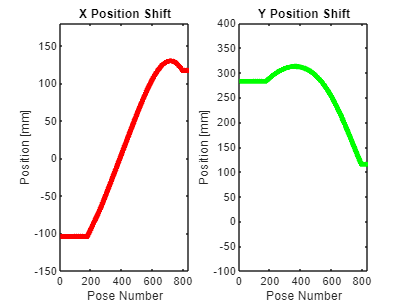

make_video = false;

load(".\From Jason\Rx 23.5 Ry 23.5 Variables\Poses.mat");
Poses = round(Poses,2);
figure('Name','Rx 23.5 Ry 23.5',"WindowState","maximized")
for i=1:size(Poses,2)
    subplot(1,2,1);
    plot(Poses(1,1:i),'-r','LineWidth',4)
    title('X Position Shift')
    xlabel('Pose Number')
    ylabel('Position [mm]')
    xlim([0 size(Poses,2)])
    ylim([-150 180])
    subplot(1,2,2)
    plot(Poses(2,1:i),'-g','LineWidth',4)
    title('Y Position Shift')
    xlabel('Pose Number')
    ylabel('Position [mm]')
    xlim([0 size(Poses,2)])
    ylim([-100 400])
    drawnow;
    if make_video
        G(i) = getframe(gcf); % Creates frame of each incremental movement from top view
    end
end

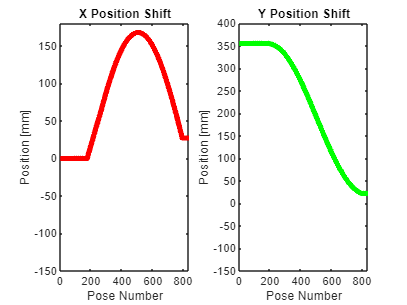

load(".\From Jason\Rx 35 Ry 0 Variables\Poses.mat");
Poses = round(Poses,2);
figure('Name','Rx 35 Ry 0',"WindowState","maximized")
for i=1:size(Poses,2)
    subplot(1,2,1);
    plot(Poses(1,1:i),'-r','LineWidth',4)
    title('X Position Shift')
    xlabel('Pose Number')
    ylabel('Position [mm]')
    xlim([0 size(Poses,2)])
    ylim([-150 180])
    subplot(1,2,2)
    plot(Poses(2,1:i),'-g','LineWidth',4)
    title('Y Position Shift')
    xlabel('Pose Number')
    ylabel('Position [mm]')
    xlim([0 size(Poses,2)])
    ylim([-150 400])
    drawnow;
    if make_video
        H(i) = getframe(gcf); % Creates frame of each incremental movement from top view
    end
end

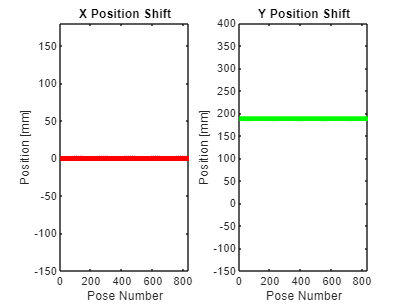

load(".\From Jason\Rx 0 Ry 0 Variables\Poses_with_Adapt.mat");
Poses = round(Poses,2);
figure('Name','Rx 0 Ry 0',"WindowState","maximized")
for i=1:size(Poses,2)
    subplot(1,2,1);
    plot(Poses(1,1:i),'-r','LineWidth',4)
    title('X Position Shift')
    xlabel('Pose Number')
    ylabel('Position [mm]')
    xlim([0 size(Poses,2)])
    ylim([-150 180])
    subplot(1,2,2)
    plot(Poses(2,1:i),'-g','LineWidth',4)
    title('Y Position Shift')
    xlabel('Pose Number')
    ylabel('Position [mm]')
    xlim([0 size(Poses,2)])
    ylim([-150 400])
    drawnow;
    if make_video
        I(i) = getframe(gcf); % Creates frame of each incremental movement from top view
    end
end

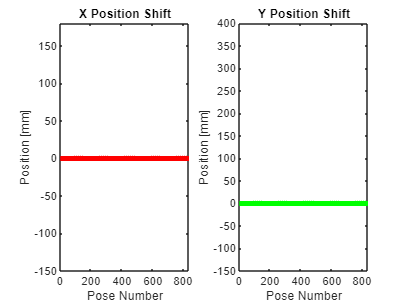

load(".\From Jason\Rx 0 Ry 0 Variables\Poses.mat");
Poses = round(Poses,2);
figure('Name','Rx 0 Ry 0 without Adaptive Pose',"WindowState","maximized")
for i=1:size(Poses,2)
    subplot(1,2,1);
    plot(Poses(1,1:i),'-r','LineWidth',4)
    title('X Position Shift')
    xlabel('Pose Number')
    ylabel('Position [mm]')
    xlim([0 size(Poses,2)])
    ylim([-150 180])
    subplot(1,2,2)
    plot(Poses(2,1:i),'-g','LineWidth',4)
    title('Y Position Shift')
    xlabel('Pose Number')
    ylabel('Position [mm]')
    xlim([0 size(Poses,2)])
    ylim([-150 400])
    drawnow;
    if make_video
        J(i) = getframe(gcf); % Creates frame of each incremental movement from top view
    end
end


if make_video
    % Create video of animation
    movie(G);
    movie(H);
    movie(I);
    movie(J);
    % create the video writer

    writerObj_G = VideoWriter('Hexapod Robot Rx 23.5 Ry 23.5 Pose Simulation - 40fsp - SD');
    writerObj_H = VideoWriter('Hexapod Robot Rx 35 Ry 0 Pose Simulation - 40fsp - SD');
    writerObj_I = VideoWriter('Hexapod Robot Rx 0 Ry 0 Pose Simulation - 40fsp - SD');
    writerObj_J = VideoWriter('Hexapod Robot Rx 0 Ry 0 Pose Simulation without Adaptive Pose - 40fsp - SD');

    writerObj_G.FrameRate = 40;
    writerObj_H.FrameRate = 40;
    writerObj_I.FrameRate = 40;
    writerObj_J.FrameRate = 40;
    % set the seconds per image
    % open the video writer
    open(writerObj_G);
    open(writerObj_H);
    open(writerObj_I);
    open(writerObj_J);
    % write the frames to the video
    for i=1:length(G)
        % convert the image to a frame
        frame_G = G(i);
        frame_H = H(i);
        frame_I = I(i);
        frame_J = J(i);
        writeVideo(writerObj_G, frame_G);
        writeVideo(writerObj_H, frame_H);
        writeVideo(writerObj_I, frame_I);
        writeVideo(writerObj_J, frame_J);
    end
    % close the writer object
    close(writerObj_G);
    close(writerObj_H);
    close(writerObj_I);
    close(writerObj_J);
end